# 姿勢とライトカーブをstaticに生成 (位置固定)

as a true values for verifying GP_static

clc
clear

### add path for functions

curdir = pwd;
addpath(genpath(strcat(curdir, '/../../yoshimuLibrary/'))); % genpathでサブディレクトリ以下全てのpathを取得
addpath(genpath(strcat(curdir, '/../../hara_functions/')));

### flags

fixed = 'random' % "random" or "tleInit" or ""

fixed = 'random'

### constants and satellite parameters

const = orbitConst; % for orbital motion
earthVSOP = vsopConst; % for earth orientation

% for time calculation
iau06 = readIAU06;
leapJD = leapS; % load database
fname = "EOP_20_C04_one_file_1962-now.txt";
eopDataAll = readEOP(fname);


model = 2; % 1: flatplate, 2: boxWing

if model == 1
    objName = 'flatPlate.obj';
    nCompo = 1; % # of object in .obj file
    sat = readSC(objName, nCompo); % satellite shape and optical parameters

    sat.J = diag([10, 15, 20]); % moment of inertia, kgm^2
    sat.m = 50; % mass, kg
    sat.nu = ones(size(sat.faces,1),1) .* 800; %とりあえずベタうち
    sat.nv = ones(size(sat.faces,1),1) .* 800;
    sat.F0 = ones(size(sat.faces,1),1) .* 0.5;
    sat.kappa = 0.0; % thermal emissivity
elseif model == 2
    objName = 'boxWing.obj';
    nCompo = 3; % # of object in .obj file
    sat = readSC(objName, nCompo); % satellite shape and optical parameters

    % sat.J = diag([45, 50, 60]); % moment of inertia, kgm^2
    sat.J = diag([55, 40, 65]);
    sat.m = 100; % mass, kg
    %   optical parameters at wing (manually...)
    % sat.Ca(193:end,:) = 0.1; % absorption
    % sat.Cd(193:end,:) = 0.6; % diffuse
    % sat.Cs(193:end,:) = 0.3; % specular
    sat.Ca = 0.0; % absorption
    sat.Cd = 0.7; % diffuse
    sat.Cs = 1 - sat.Cd; % specular
    sat.nu = ones(size(sat.faces,1),1) .* 800; %とりあえずベタうち
    sat.nv = ones(size(sat.faces,1),1) .* 800;
    sat.F0 = ones(size(sat.faces,1),1) .* 0.5; % [0, 1]
    sat.kappa = 0.0; % thermal emissivity
else
    error('invalid model flag');
end

Reading Object file : boxWing.obj
  % Blender v2.83.1 OBJ File: 'boxWing.blend'
  %www.blender.org
Reading Material file : boxWing.mtl
  % Blender MTL File: 'boxWing.blend'
  % Material Count: 2
Finished Reading Material file
Finished Reading Object file


ans =    242     3


ans =    472     3


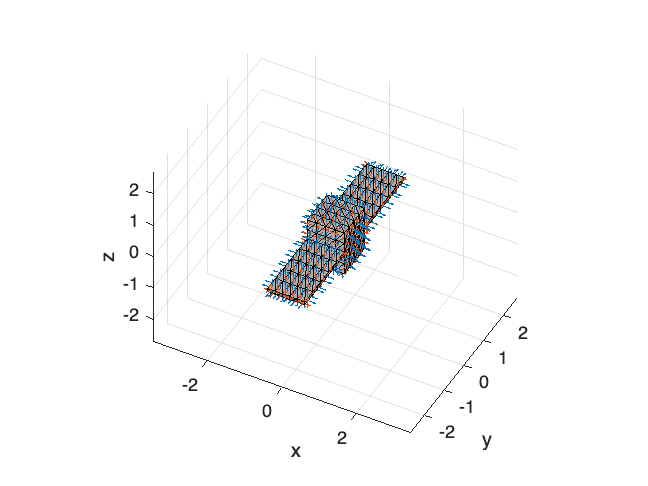

showSC(sat,"Normal","on") % visualize satellite

### initial condition

#### attitude

% qIni = zyx2q(4, -1.3222, 1.4059, 0); % initial quaternion, q(4) is the scalar part
qIni = [0, 0, 0, 1];
% wIni = deg2rad([0.1, -0.4, -0.2]); % initial angular rate, rad/s for asymmetric body
wIni = deg2rad([0.1, -0.1, -0.25]); % for random, まあまあ綺麗に推定できる初期条件...
% wIni = deg2rad([0.05, -0.08, -0.1]); 
% wIni = deg2rad([0.2, 0.15, -0.15]);
% wIni = deg2rad([-0.02, 0.01, 0.05]); % for tleInit
% wIni = deg2rad([-0.01, -0.01, 0.02]);
% wIni = deg2rad([0, 0.3, 0.2]);

xIni = [qIni, wIni];

#### orbit

cowellは解かない

% if TLE == 1
%     tle = readTLE('JCSAT2.txt', const);
% else
%     a = 42164.91220781728; % [km]
%     e = 0.000215800000000; % [-], eccentricity
%     inc = 0.000938987137573; % [rad]
%     W = 4.918899828139163; % [rad], right ascention of the ascending node
%     w = 0.876621287411436; % [rad], argument of perigee
%     m = 1.585708419923936; % [rad], mean anomaly at epoch
% 
%     tle.oe = [a e inc W w m];
%     tle.jd = 2.458535992836310e+06; % [day], Julian day of terestrial time

% end

### ode

tstep = 1;
tspan = 0:tstep:60*10;

options = odeset('RelTol',1e-9,'AbsTol',1e-9);
[t_, x_] = ode89(@(t,x)eomAtti_h(t,x,sat), tspan, xIni, options);

q = x_(:,1:4);
w = x_(:,5:7);

tmp = q2zyx(4, q);
phi = tmp(:,1);
theta = tmp(:,2);
psi = tmp(:,3);

### sat-obs-Sun positions

とりあえず．genTrainStatic.mlxのコードのposition と一致させることに注意．

rng(1, "twister"); % 乱数の再現性

% satellite position
satPos = [0, 0, 0]; % sat is origin

if strcmp(fixed, "random")
    % observer position
    obsPos = [36000, 0, 0]; % 高度36000km 
    obsPos = obsPos .* 10^3; % [m]
    
    % sun position
    nSun = 1; % 太陽の位置の数
    sunAzi = pi .* rand(nSun, 1) - pi/2;
    sunEle = acos(1 - 2 .* rand(nSun, 1));
    sunPos = const.AU .* [cos(sunAzi).*sin(sunEle), sin(sunAzi).*sin(sunEle), cos(sunEle)] % km
    sunPos = sunPos .* 10^3; % [m]
elseif strcmp(fixed, "tleInit")
    % jdHistory = tle.jd + s2day(t_); % time history in Julian day
    % jdHistory = tle.jd;
    % [yy, mm, dd, hh, m, s] = jd2gc(jdHistory);
    % utc = datetime([yy, mm, dd, hh, m, s]); % UTC (datetime format)
    
    
    % とりあえずべたうちでscjsat.tleの初期位置と合わせてみる -----------
    obsPos = [-2.0005, -3.2290, 0.3506] .* 10^4; % [km]
    obsPos = obsPos .* 10^3; % [m]
    sunPos = [1.3096, -0.6315, -0.2736] .* 10^8; % [km]
    sunPos = sunPos .* 10^3; %[m]
end

sunPos = 1.0e+08 *

    1.2975   -0.3461   -0.6592


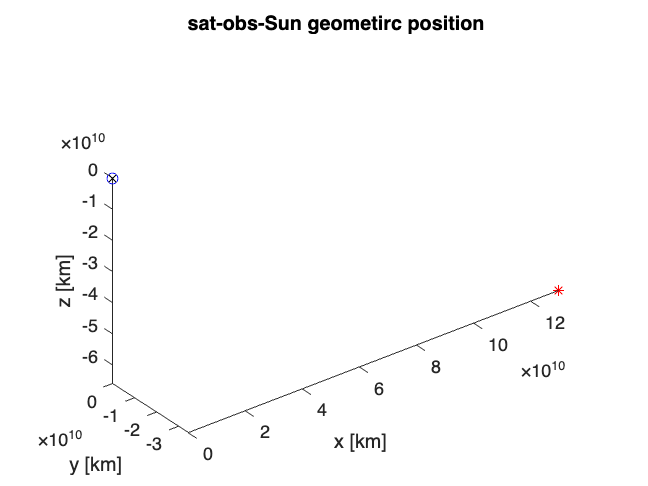


% plot ------
figure
plot3(sunPos(:,1), sunPos(:,2), sunPos(:,3),'r*');
hold on;
plot3(satPos(:,1), satPos(:,2), satPos(:,3), 'kx');
hold on;
plot3(obsPos(:,1), obsPos(:,2), obsPos(:,3), 'bo');
% tmp = gmst(jdHistory(end));
% drawEarth(tmp, 0.6, const);
xlabel('x [km]'), ylabel('y [km]'), zlabel('z [km]')
title("sat-obs-Sun geometirc position");
axis equal

### generate light curves

satPos = repmat(satPos, size(tspan, 2), 1);
obsPos = repmat(obsPos, size(tspan, 2), 1);
sunPos = repmat(sunPos, size(tspan, 2), 1);
% q = repmat(q, nSun, 1);

[mApp, ~] = lc(sat, 4, q, satPos, obsPos, sunPos, 1, 'AS'); % tspanx1

### show figs

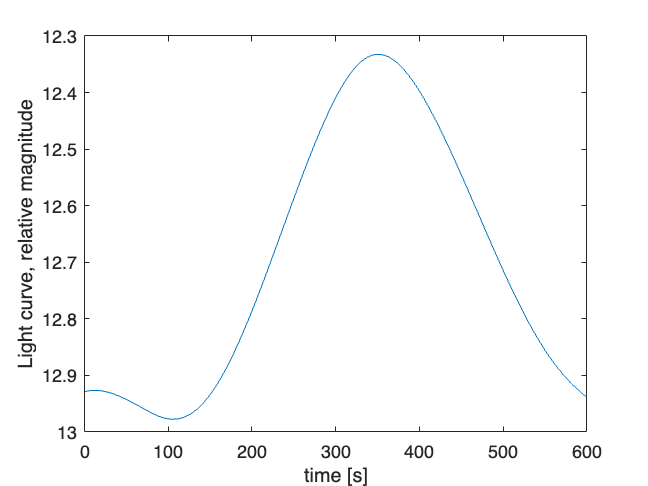

figure
plot(t_, mApp)
xlabel('time [s]'), ylabel('Light curve, relative magnitude')
set(gca, 'YDir', 'reverse')


%% attitude
figure % quaternion
tFig = tiledlayout(4,1), nexttile

tFig =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [4 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


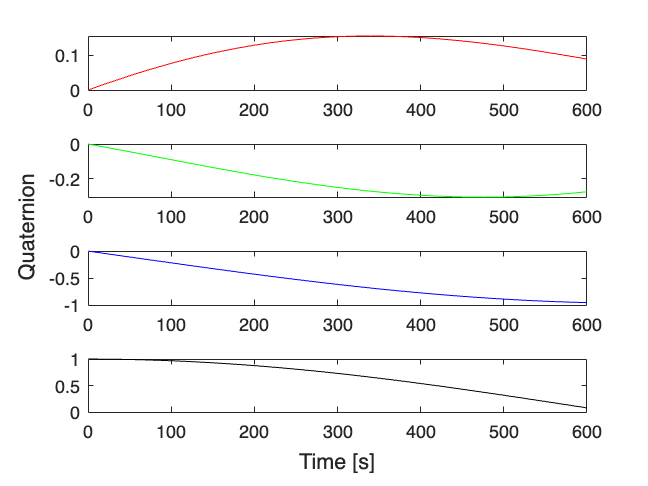

plot(t_,q(:,1),'r'), nexttile
plot(t_,q(:,2),'g'), nexttile
plot(t_,q(:,3),'b'), nexttile
plot(t_,q(:,4),'k')
xlabel(tFig, 'Time [s]')
ylabel(tFig, 'Quaternion ')

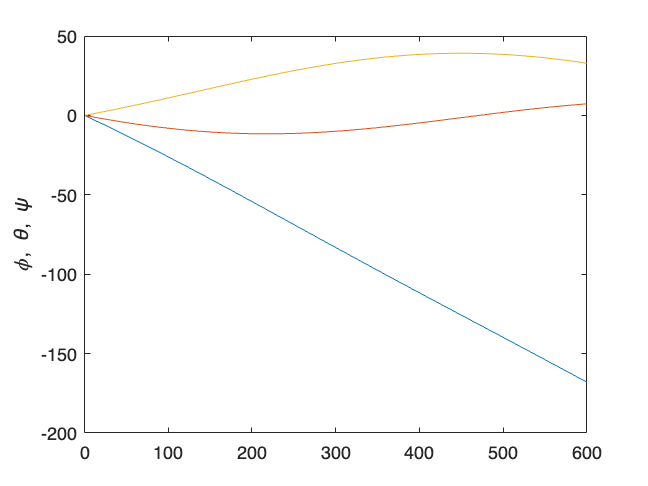


figure % attitude angle
plot(t_, rad2deg(phi))
hold on
plot(t_, rad2deg(theta))
plot(t_, rad2deg(psi))
ylabel('\phi, \theta, \psi')

### save data

fName = strcat(objName(1:end-4), "_lcAtti_staticFixed");
saveName = strcat(fName, '.mat');
save(saveName, 't_', 'mApp', 'q', 'phi', 'theta', 'psi', 'w', 'sat', 'satPos', 'obsPos', 'sunPos')